# **Demo3: Long Short-Term Memory (LSTM)**

Copyright 2018 The MathWorks, Inc.

In this demo, we will fit deep learning algorithm (LSTM) on trading data with balanced class of response variable. The trained model will be backtested using both in-sample and out-of-sample. The position is assumed to open at the end of the day in whcih signal is created and close in the end of next trading day.

## **Setup**

clear
clc
close all
rng(0);
warning off
load data3_demo3.mat
tDay = 252; % number of trading day per annum

## **Run **LSTM Networks

Define LSTM layers

hiddenUnit = 1000;
layers = [ sequenceInputLayer(nFeatures)
           lstmLayer(hiddenUnit,'OutputMode','last')
           fullyConnectedLayer(2)
           softmaxLayer()
           classificationLayer]

layers =   5x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 14 dimensions
     2   ''   LSTM                    LSTM with 1000 hidden units
     3   ''   Fully Connected         2 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex

Set training options

opts = trainingOptions('sgdm',...
    'Verbose',1,...
    'VerboseFrequency',50,...
    'Plots','training-progress', ...
    'shuffle', 'never',...
    'LearnRateSchedule','piecewise',...
    'InitialLearnRate', 0.01,...
    'MiniBatchSize',100,...
    'MaxEpochs',10);

Train the network using traning data (a subset of in-sample data) with balanced class response variable.

Training on single CPU.
|=========================================================================================|
|     Epoch    |   Iteration  | Time Elapsed |  Mini-batch  |  Mini-batch  | Base Learning|
|              |              |  (seconds)   |     Loss     |   Accuracy   |     Rate     |
|=========================================================================================|
|            1 |            1 |         1.58 |       0.6932 |       50.00% |       0.0100 |
|            3 |           50 |        17.16 |       0.6932 |       50.00% |       0.0100 |
|            6 |          100 |        27.07 |       0.6888 |       58.00% |       0.0100 |
|            9 |          150 |        39.37 |       0.6938 |       49.00% |       0.0100 |
|           10 |          170 |        43.31 |       0.6946 |       44.00% |       0.0100 |
|=========================================================================================|


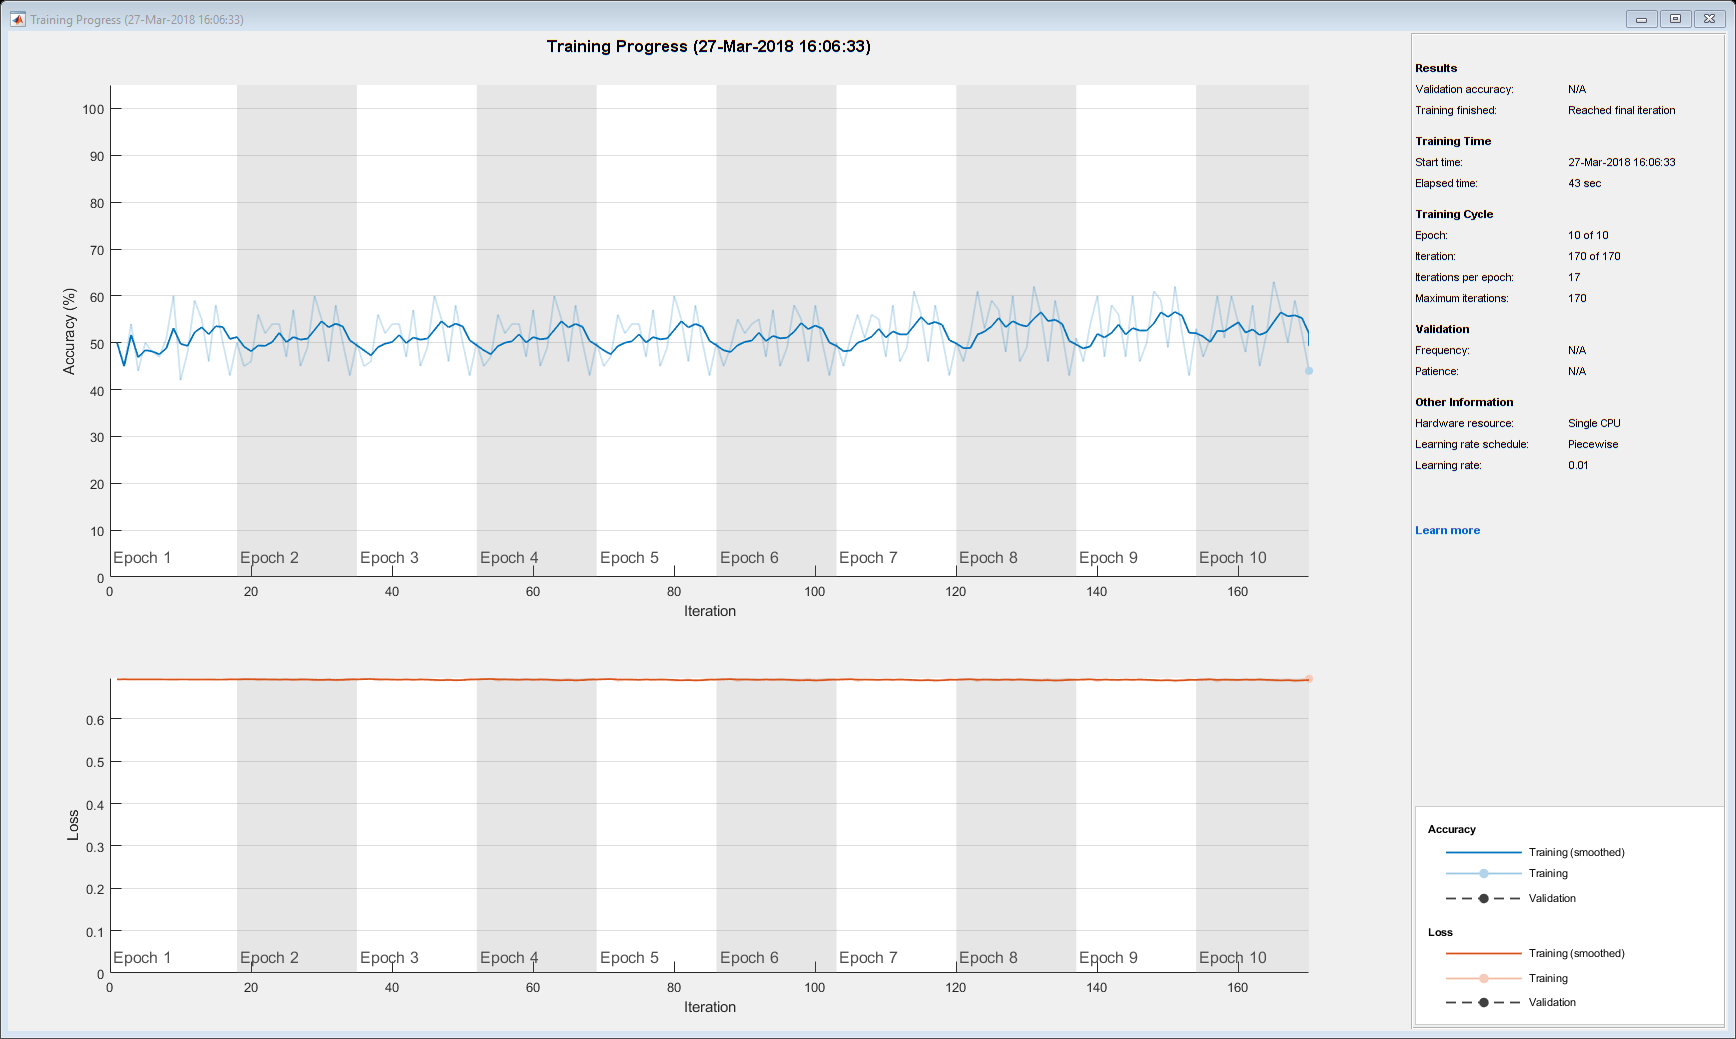

net = trainNetwork(xTrain,yTrain,layers, opts);

## Backtest the strategy (In-sample)

Use the trained network to classify testing data and dsplay data using confusion matrix where 1 = Buy and 2 = Sell

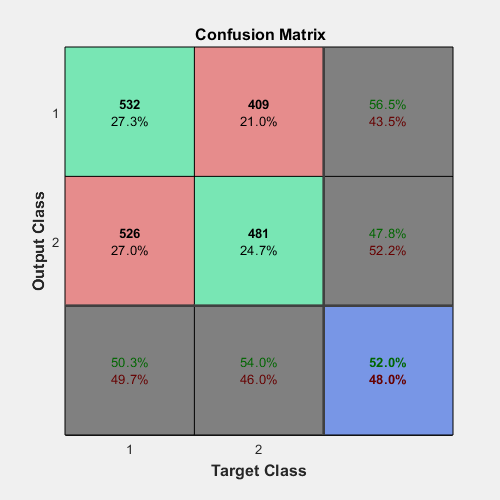

yPredInSample = classify(net,xInSample);
% display(table([1;2],categories(yPredInSample)))
displayConfusion(yInSample,yPredInSample)

Assume that we could buy at the end of trading period when the signal is generated and sell at the end of next trading period.

signal = (1*(yPredInSample == 'Buy')-0.5)*2;
portReturns1 = signal(1:end-1).*yRetInSample(2:end);
portValue1 = ret2tick(portReturns1);
sharpeRatio1 = sharpe(portReturns1,0)*sqrt(tDay)

sharpeRatio1 = 0.6384

Visualize the equity curves of three demos (1-3) wtih initial portfolio value of 1.

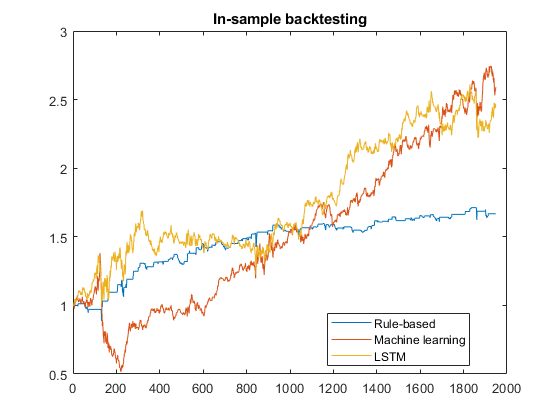

figure
openfig('plotInSample_Demo2.fig');
hold on
plot(portValue1)
title('In-sample backtesting')
legend('Rule-based','Machine learning','LSTM','Location','best')
hold off
savefig('plotInSample_Demo3.fig');

## Backtest the strategy (Out-of-sample)

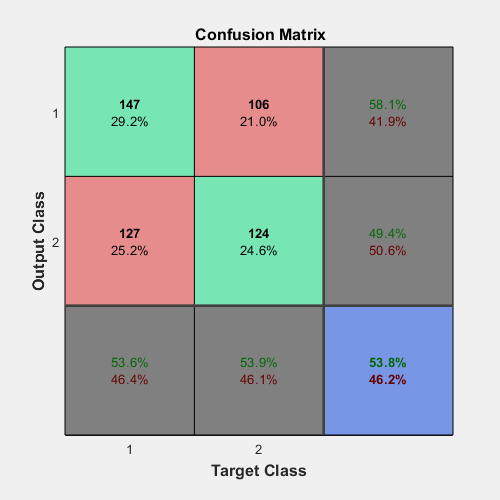

yPredOutSample = classify(net,xOutSample);
displayConfusion(yOutSample,yPredOutSample)

Assume that we could buy at the end of trading period when the signal is generated and sell at the end of next trading period.

signal = (1*(yPredOutSample == 'Buy')-0.5)*2;
portReturns2 = signal(1:end-1).*yRetOutSample(2:end);
portValue2 = ret2tick(portReturns2);
sharpeRatio2 = sharpe(portReturns2,0)*sqrt(tDay)

sharpeRatio2 = 0.9929

Visualize the equity curves of three demos (1-3) wtih initial portfolio value of 1.

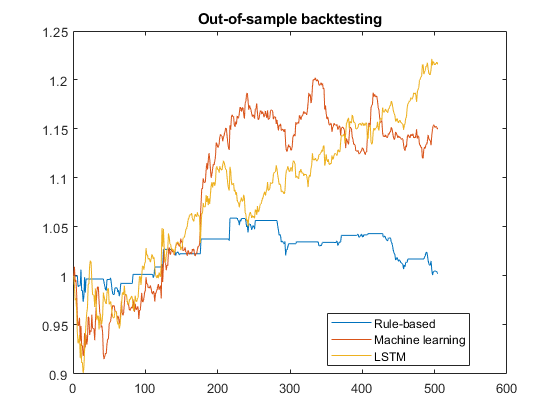

figure
openfig('plotOutSample_Demo2.fig');
hold on
plot(portValue2)
title('Out-of-sample backtesting')
legend('Rule-based','Machine learning','LSTM','Location','best')
hold off
savefig('plotOutSample_Demo3.fig');

close all